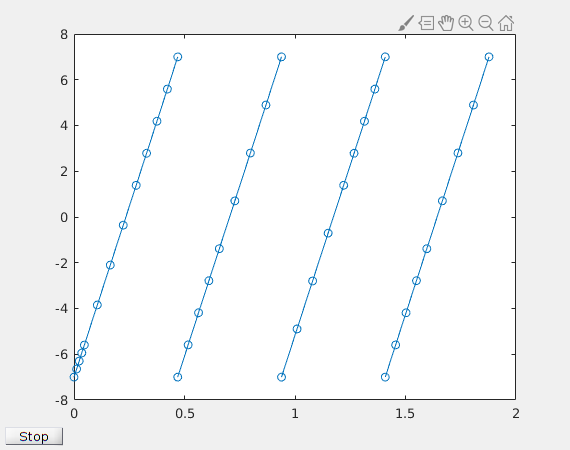

clf
a = 2; c = 1; H = 30;       %distances
s = 7;                      %Stride length    
x0 = [-s; 30];              %I.C. [position; velocity]
tstart = 0; tfinal = 10;    %max time per swing

refine = 4;
options = odeset('Events',@events,'OutputFcn',@odeplot,'OutputSel',1,'Refine',refine);

fig = figure;
vel = []; time = []; dist = []; sum = []; foot = [];

for i = 1:4                 %number of steps
    % Solve until the first terminal event.
    [t,x] = ode45(@(t,x) odefcn(t,x,a,c,H), [tstart tfinal], x0, options);
   if ~ishold
      hold on
   end
      
   % Set the new initial conditions
   x0(1) = -1*s;                %theta distaces new position IC
   x0(2) = 1*x(end,2);            %v- = 1*v+ no loss after impact
   
   nt = length(t);
   
   % A good guess of a valid first timestep is the length of the last valid
   % timestep, so use it for faster computation.  'refine' is 4 by default.
   options = odeset(options,'InitialStep',t(nt)-t(nt-refine),'MaxStep',t(nt)-t(1));
      
   tstart = t(nt);
   
   vel = [vel; x(:,2)];
   time = [time; t];
   
   %modifying position to save
   if i == 1 
       dist = x(:,1);
   else
       sum = x(:,1) + abs(x(1,1)) + dist(end,1);
       dist = [dist; sum];
   end
   foot = [foot; (x(1,1)+x(end,1))/2*ones(length(x(:,1)),1) + dist(end,1)  - x(end,1)]; %remember foot location
   
   if x0(2) <= 0
       break                    %stop if velocity is <= 0
   end
end

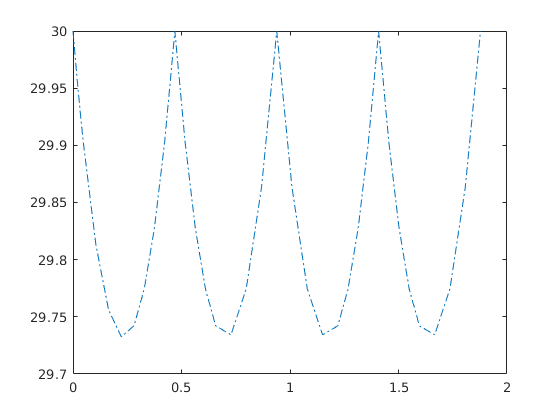

clf
plot(time,vel,'-.')

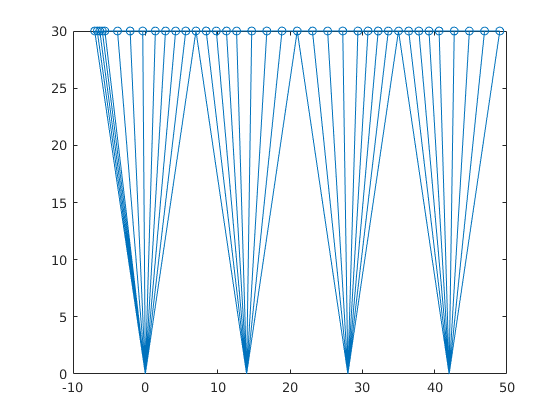

plot(dist,30*ones(1,length(dist)),'-o'), hold on
for k = 1:length(dist)
    plot([dist(k),foot(k)],[H, 0],'Color',[0, 0.4470, 0.7410]),
end
hold off

axis 'auto y'


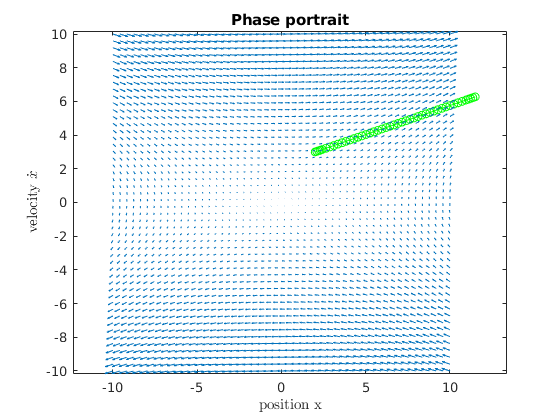

%Phase portrait

%States: x1 = pos,      x2 = vel
        %x1dot = x2,    x2dot = acc = (a-c)*g/yh*x1
[x1, x2] = meshgrid(linspace(-10,10,50), linspace(-10,10,50));
x1dot = x2; 
x2dot = (a-c)*9.81/H.*x1;

%Limit cycle
[t,x]=ode45(@(t,xx) odefcn(t,x,a,c,H),[0 10],[2;3]);
plot(x(:,1),x(:,2),'go-'), hold on

quiver(x1, x2, x1dot, x2dot), hold off
axis equal
xlabel('position x','interpreter','latex'), ylabel('velocity $\dot{x}$','interpreter','latex')
title('Phase portrait')

function [stride,isStride,direction] = events(t,x)
%global stride_length;
stride = double(x(1) < 7);      % The value that we want to be zero, logical in this case
isStride = 1;                   % Halt integration 
direction = 0;                  % The zero can be approached from either direction
end

function dxdt = odefcn(t,x,a,c,H)
    dxdt = zeros(2,1);
    dxdt(1) = x(2);                 %dxdt = velocity x_dot = x(2)
    dxdt(2) = (a-c)*9.81/H.*x(1);   %x(1) = position x
end